% 2 sample t test on trial vectors (C=0 vs all other C's, one state at a time)

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;

% LOCO NO PUP

% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeloRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% run group CRF matrix
state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeHiRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% need output from HISTO code to run stats:

%durat = 1:length(uniqueDurations);
durat = 1

durat = 1

cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7
visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control
sess = 1:nGroup

sess =      1     2     3



state = 'loRun'

state = loRun

[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     3


% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}
state = 'hiRun'

state = hiRun

[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     3


% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% picking an alpha value (correct for mult. comparisons)
n_cons = 7 % # contrasts 

n_cons = 7

denom = n_cons-1 % # comparisons

denom = 6

alf = 0.05/denom % bonferroni correction for multiple comparisons

alf = 0.0083

% for stats loop (cell below) 2 sample t test c =0 vs all other cons

%durat = 1:length(uniqueDurations);
durat = 1

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7

visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup

sess =      1     2     3


%sess = 1

% this code is similar to the histo code in that it gathers all trials across all sess for each con,
% but different in that
% it then performs a 2 sample t test and saves out the test statistics
% also the histo function saves all the trials as nested cell array, which I don't need here

clear h_p_cil_cih__tstats_AllPairs
clear tstats_AllPairs

clear h_p_cil_cih__tstats_AllPairs_AllPts
clear tstats_AllPairs_AllPts

clear h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs
clear tstats_AllPairs_AllPts_AllDurs

for d = durat
    
    for i = visArea
        
        clear c
        for c = 1 % zero contrast
        %for c = 1
        %for c = 1:length(uniqueContrasts)
            
            % get df for each trial vector across all sessions, c = 0
            clear zeroCon_lo_dthithCthNth_pkDfEachTrial
            zeroCon_lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear zeroCon_hi_dthithCthNth_pkDfEachTrial
            zeroCon_hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                zeroCon_lo_dthithCthNth_pkDfEachTrial = [zeroCon_lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
                zeroCon_hi_dthithCthNth_pkDfEachTrial = [zeroCon_hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
            end % end n loop - now have all mean peak df values for each trial (c=0), all sessions pooled
            
        end % end c = 0 loop

%             %%subplot(2,4,c)
%               
%             % 2 sample T-TEST on c = 0 vs all other c's, one beh state at a time) 
%             [h,p,ci,t_stats] = ttest2(lo_dthithCthNth_pkDfEachTrial,hi_dthithCthNth_pkDfEachTrial,'Alpha',alf);
%             
%             %%title(sprintf('c=%1.0f, va=%1.0f, h=%1.0f, p=%0.4f',c,i,h,p))
%             
%             %%axis square
%             
%             % COLLECT t-stat params
%             h_p_cil_cih__tstats_AllPairs(1,c) = h;
%             h_p_cil_cih__tstats_AllPairs(2,c) = p;
%             h_p_cil_cih__tstats_AllPairs(3,c) = ci(1,1);
%             h_p_cil_cih__tstats_AllPairs(4,c) = ci(1,2);
%             tstats_AllPairs{1,c} = t_stats;
            
            
            % OLD CODE
            
        % for each contrast * except c = 0 (cuz will get N/A)
        clear c
        for c = cont(2:end)
            
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
            
                % get values for 1st sesson, cth dth ith trials
                 lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                 hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
           
            end % end n loop
            
            % LO, C=0 vs CTH CON
            % c=0 distribution vs every each cth distribution
            %[h,p,ci,t_stats] = ttest2(zeroCon_lo_dthithCthNth_pkDfEachTrial,lo_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            [h,p,ci,t_stats] = ttest2(zeroCon_hi_dthithCthNth_pkDfEachTrial,hi_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            
            h_p_cil_cih__tstats_AllPairs(1,c-1) = h; % c-1 so index doesn't start at 2
            h_p_cil_cih__tstats_AllPairs(2,c-1) = p;
            h_p_cil_cih__tstats_AllPairs(3,c-1) = ci(1,1);
            h_p_cil_cih__tstats_AllPairs(4,c-1) = ci(1,2);
            tstats_AllPairs{1,c-1} = t_stats;

        end % end contrast loop
        
        % collect stats x contrast grid for each point
        h_p_cil_cih__tstats_AllPairs_AllPts(:,:,i) = h_p_cil_cih__tstats_AllPairs;
        tstats_AllPairs_AllPts{i,:} = tstats_AllPairs;
        
    end % end i loop
    
    h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(:,:,:,d) = h_p_cil_cih__tstats_AllPairs_AllPts;
    tstats_AllPairs_AllPts_AllDurs{d,:} = tstats_AllPairs_AllPts;
   
    
end % end d loop

% stats param x comparison contrast x points
size(h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)

ans =      4     6     5


size(tstats_AllPairs_AllPts_AllDurs)

ans =      1     1



%loBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs = h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs;
%hiBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs = h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs;

% for plotting, get CRF
% getting mean CRF ACROSS SESSIONS & STD ERR ACROSS SESSIONS 
% LO BEH STATE
% note: this code is roughtly the same as that w/in code from groupMeta.mlx wehere CRFs are calculated 
% and plotted from the data in, 
% except this code doesn't make fig w/in same function, and outputs the matrix to be plotted:
[loRun_mnCRF_acrossSess_AllDurAllPts,loRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loRun_mnCRF_acrossSess_AllDurAllPts = size(loRun_mnCRF_acrossSess_AllDurAllPts)

size_loRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_loRun_stdErrCRF_acrossSess_allPts = size(loRun_stdErrCRF_acrossSess_allPts)

size_loRun_stdErrCRF_acrossSess_allPts =      5     7


% HI BEH STATE
[hiRun_mnCRF_acrossSess_AllDurAllPts,hiRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiRun_mnCRF_acrossSess_AllDurAllPts = size(hiRun_mnCRF_acrossSess_AllDurAllPts)

size_hiRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_hiRun_stdErrCRF_acrossSess_allPts = size(hiRun_stdErrCRF_acrossSess_allPts)

size_hiRun_stdErrCRF_acrossSess_allPts =      5     7


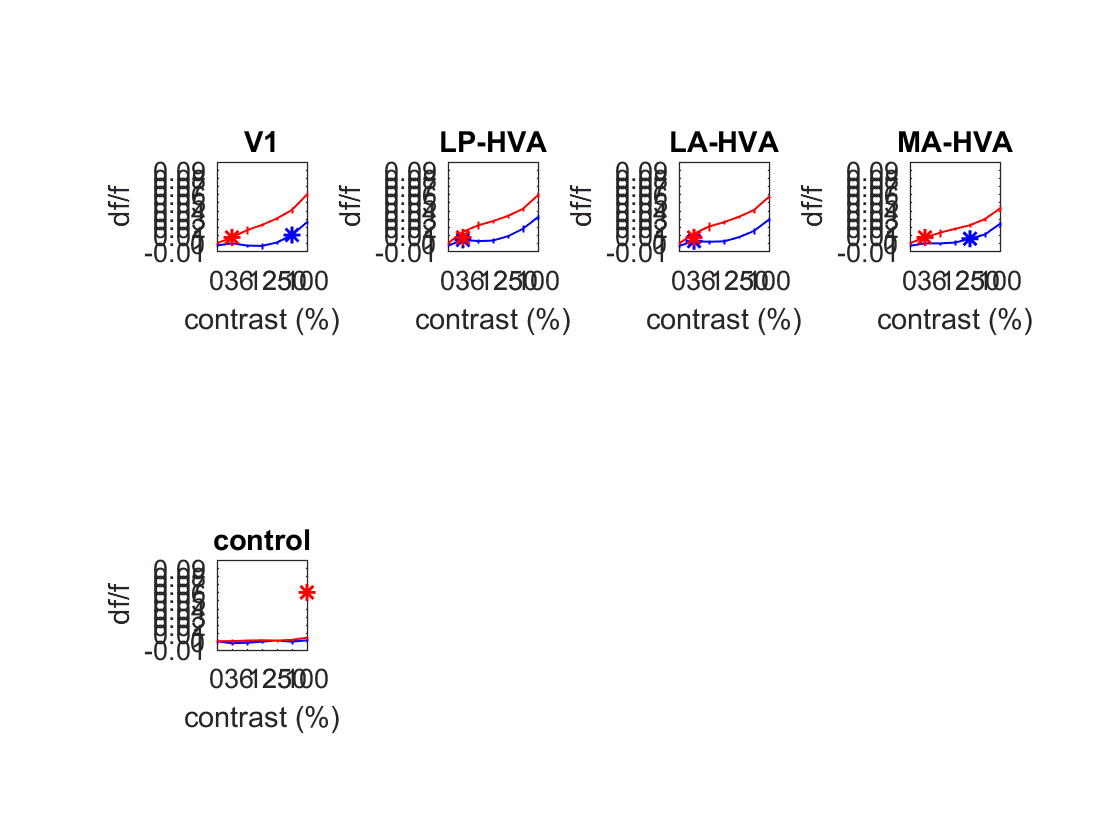

% for crf figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT CRFs w/asterisks

figure

% for each duration
clear d
for d = durat
    
    % for each point
    clear i
    for i = visArea
        
        % Plot the CRF for LO beh state
        
        % make a sub plot
        subplot(2,4,i)
        
        % plot LO beh state CRF
        x_axis = 1:length(uniqueContrasts);
        %plot(x_axis,mnCRF_acrossSess_AllDurAllPts_loBehState(i,:),'b')
        errorbar(x_axis,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'-b','LineWidth',0.75) 
        hold on
        % plot HI beh state CRF
        %plot(x_axis,mnCRF_acrossSess_AllDurAllPts_hiBehState(i,:),'r')
        errorbar(x_axis,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r','LineWidth',0.75)
        
        hold on
        
        % legend(stateLegend)
        
        % reset asterisk counter for each vis area/beh state:
        counter = 0; % once counter = 1, stop plotting asterisk
         
        % for LO beh state
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(loBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)
            
            if counter == 0
            
                if loBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                    hold on
                    
                    plot(com+1,loRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'b*','LineWidth',1.1)
                    
                    xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
                    %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
                    set(gca,'xtick',1:7); 
                    set(gca,'xticklabel',xt);
                    
                    %H=sigstar({{xt{1},xt{min(find(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
                    %set(H,'color','b')
                    
                    counter = counter + 1;
                
                end % end plot if statement
               
            end % end counter if statement
            
        end % end com loop
        
        % plot asterisk at c=0 df value
        %plot(1,mnCRF_acrossSess_AllDurAllPts_hiBehState(i,1),'r*')
        % make a line
        %y = mnCRF_acrossSess_AllDurAllPts_hiBehState(i,1);
        %line([0,5],[y,y])
        
        hold on
        
        % LO
        % set counter to zero for each state
        counter = 0;
        
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(hiBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)
            
            if counter == 0
            
                if hiBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                    hold on
                    
                    plot(com+1,hiRun_mnCRF_acrossSess_AllDurAllPts(1,com+1),'r*','LineWidth',1.1)
                    clear xt
                    xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
                    set(gca,'xtick',1:7); 
                    set(gca,'xticklabel',xt);

                    %H=sigstar({{xt{1},xt{min(find(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
                    %set(H,'color','r')
                    
                    %ylim(yLimit)
        
                    counter = counter + 1;
                    
                end % end plot if statement
               
            end % end counter if statement
            
        end % end com loop
            
        % legend(stateLegend)
%         % reset asterisk counter for each vis area/beh state:
%         counter = 0; % once counter = 1, stop plotting asterisk
%          
%         % for LO beh state
%         % for each comparison between states at cth contrast, if h ==1, overlay a star (colored)
%         clear c
%         for c = cont
%             
%         % if you only want to put the star for the 1st contrast to deviate from zero, use another if statement:
%         %if counter == 0
%         
%         for c = cont % for each contrast at this point, 
%         % loop thru the stats params,
%         % if h = 1, plot asterisk
%         
%             % if h = 1 for the cth con, ith point (*NO* durs right now despite var name saying so! its 4 x 7 x 5)
%             if h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(1,c,i) == 1
%             %if loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,com,i) == 1
%                 
%                 %plot(com+1,loRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'b*','LineWidth',1.1)
%                 %plot(c,loRun_mnCRF_acrossSess_AllDurAllPts(i,c),'k*','LineWidth',1.1) % not really durs in this var
%                 plot(c,0.08,'k*','LineWidth',1.1)
%                     
%                 xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%                 %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
%                 set(gca,'xtick',1:7); 
%                 set(gca,'xticklabel',xt);
%                     
%                 %H=sigstar({{xt{1},xt{min(find(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
%                 %set(H,'color','b')
%                     
%                 %counter = counter + 1;
%                 
%             end % end plot if statement
% 
%         end % end c loop
%         
        %hold on
        
%         % set counter to zero again for the hi beh state
%         counter = 0;
%         
%         % for each comparison, if h ==1, overlay a star (colored)
%         clear com
%         for com = 1:length(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)
%             
%             if counter == 0
%             
%                 if hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,com,i) == 1
%                 
%                     hold on
%                     
%                     %plot(com+1,hiRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'r*','LineWidth',1.1)
%                     clear xt
%                     xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%                     set(gca,'xtick',1:7); 
%                     set(gca,'xticklabel',xt);
% 
%                     H=sigstar({{xt{1},xt{min(find(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
%                     set(H,'color','r')
%                     
%                     %ylim(yLimit)
%         
%                     counter = counter + 1;
%            
%                 end % end if statement
%                 
%             end % end if statement
%             
%         end % end com loop
        
        title(reigons{i})
    
        ylim(yLimit) 
        xlim(xLimit)
    
        ylabel('df/f')
        xlabel('contrast (%)')
        
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
    
        yt = [-0.01 0 0.01 0.02 0.03 0.04 0.05 0.06 0.07 0.08 0.09];
        %yt = [-0.01 0 0.02 0.04 0.06 0.08];
        set(gca,'YTick',yt)
        
        axis square
        
    end % end i loop 
    
end % end d loop

hold on
        
        % reset asterisk counter for each vis area/beh state:
        counter = 0; % once counter = 1, stop plotting asterisk
         
        % for LO beh state
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)
            
            if counter == 0
            
                if loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                    hold on
                    
                    %plot(com+1,loRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'b*','LineWidth',1.1)
                    
                    xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
                    %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
                    set(gca,'xtick',1:7); 
                    set(gca,'xticklabel',xt);
                    
                    H=sigstar({{xt{1},xt{min(find(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
                    set(H,'color','b')
                    
                    counter = counter + 1;
                
                end % end plot if statement
               
            end % end counter if statement
            
        end % end com loop